# Laboratorio 2 

## Robótica 2021 - 1 

### Luis Alberto Chavez Castro

### Jorge Luis Reina Jara

### Edwin Alexander Casallas Moreno

##  Modelo cinemático inverso *fanuc LR Mate 200 ib*

### **Parte I, Robot y Ruta.**

El robot asignado para el desarrolllo de este laboratorio fue el modelo* fanuc LR Mate 200 ib, Se asigna un modelo de robot industrial a cada equipo de trabajo y un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentar al menos la simulación de esa ruta, pueden crear y simular otras rutas y/o otros planos..*

### Localización de ruta.

Plano - Vector, significa que la ruta que el robot va a simular debe estar en un plano normal al vector indicado en la tabla.

La ruta debe tener una de las dos formas mostradas en la figura 2. Cada grupo selecciona la que deseen.

La dimensión L debe ser aproximadamente 0,4 del alcance horizontal máximo del robot.

El grupo decide la posición de la ruta en el espacio cartesiano de manera que quede dentro del espacio diestro del robot.

la ruta seleccionada por el equipo de trabajo es la que se muestra a continuación:

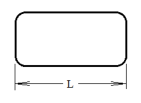

### Características y modelo del robot

Busque información t´ ecnica del robot, obtenga catálogos de fabricante, presente en el informe:

#### 1. Imagen del robot.

el Robot a modelar es el siguiente:

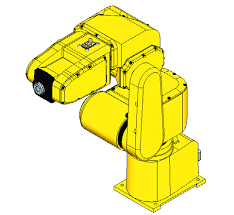

#### 2. Capacidad de carga.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB posee una capacidad de carga de 7Kg

#### 3. Alcance vertical y horizontal.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB hace parte de la gama de mini robots que buscan emular las longitudes de un brazo humano, por lo que su alcance máximo es de 717mm

En su punto máximo suerior logra 970mm en altura, medidos desde la base de instalacion del robot, hacia el frente logra su extension de 770mm desde su origen.

#### 4. Repetibilidad.

La repetiiblidad de este robot esta el rango de las centecimas de milimetro, segun el fabricante es de +/-0.01 mm.

#### 5. Gráfica(s) de espacio alcanzable.

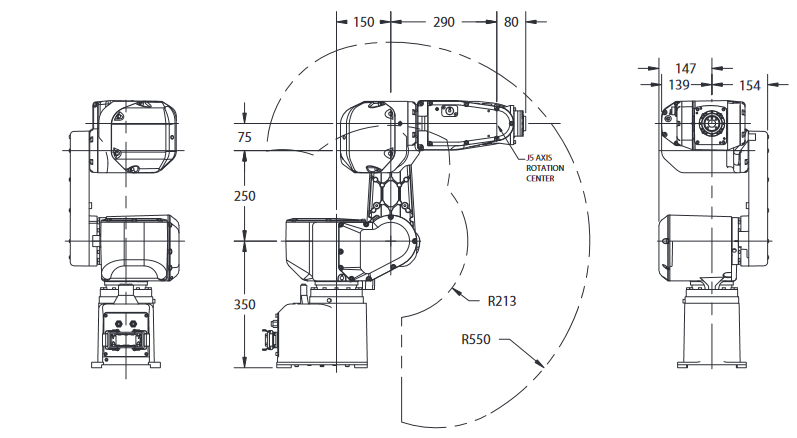

#### 6. Tabla de parámetros DH.

# 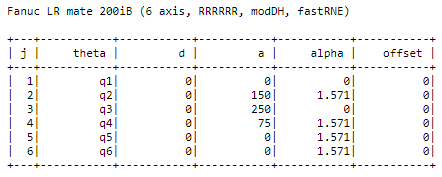

#### 7. Qué software utiliza el fabricante para diseño de celdas o programación.

el Fabricante Fanuc, emplea su propio software llamado  ROBOTSE SOFTWARE y para este robot el controlador  estándar de Fanuc  R-30iB Plus  es el que mejor se adapta a las necesidades de control de este modelo en especifico.

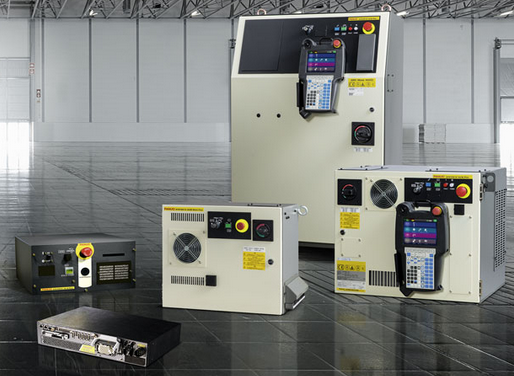

por otra parte se el mando a distancia en esta familia de robots se conoce como i-pendant y se muestra a continuacion:

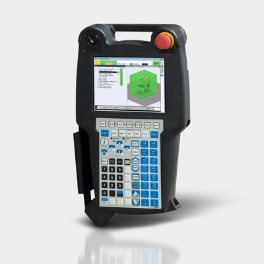

### Modelos

#### Peter Corke


%% Robot RPRRR 5 gdl
clf
clc
L1 = 2;L2 = 1; L3 = 1;L4 = 0.707*1;L5 =0.707*1; 
L4a = 0.707*1;
% ws =   [-10 10 -10   10 -10 10];
ws = [-70 80 -70 80 -20 70]*10;

 plot_options = {'workspace',ws,'scale', 1,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[700 700 1000] };

%            Theta  d   a   alpha  type mdh offset  qlim
L(1) = Link('revolute'   ,'alpha',      0,  'a',  0,     'd',    0, 'offset',    0, 'qlim',  [-2*pi/3 2*pi/3],   'modified');
L(2) = Link('revolute'   ,'alpha',   pi/2,  'a',  150,   'd',    0, 'offset',    0, 'qlim',       [0     7*1],   'modified');
L(3) = Link('revolute'   ,'alpha',      0,  'a',  250,   'd',    0, 'offset',    0, 'qlim',  [-2*pi/3 2*pi/3],      'modified');
L(4) = Link('revolute'   ,'alpha',   pi/2,  'a',  75,    'd',    0, 'offset',    0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');
L(5) = Link('revolute'   ,'alpha',   pi/2,  'a',  0,     'd',    0, 'offset',    0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');
L(6) = Link('revolute'   ,'alpha',   pi/2,  'a',  0,     'd',    0, 'offset',    0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');
Robot_Fanuc = SerialLink(L,'name','Fanuc LR mate 200iB','plotopt',plot_options)

 
Robot_Fanuc = 
 
Fanuc LR mate 200iB (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|        150|      1.571|          0|
|  3|         q3|          0|        250|          0|          0|
|  4|         q4|          0|         75|      1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|          0|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0      



%%
Robot_Fanuc.tool = [ 0  0   1  L5;...
               1  0   0  0 ;...
               0  1   0  0 ;...
               0  0   0  1  ];

%%
q = [0 0 0 0 0 0];

Robot_Fanuc.teach(q)

%%
hold on
trplot(eye(4),'length',2 )

%% Solucion problena geometrico directo
TCP = Robot_Fanuc.fkine(q)

TCP =          0         0    1.0000  475.7070
    1.0000    0.0000         0         0
   -0.0000    1.0000         0         0
         0         0         0    1.0000


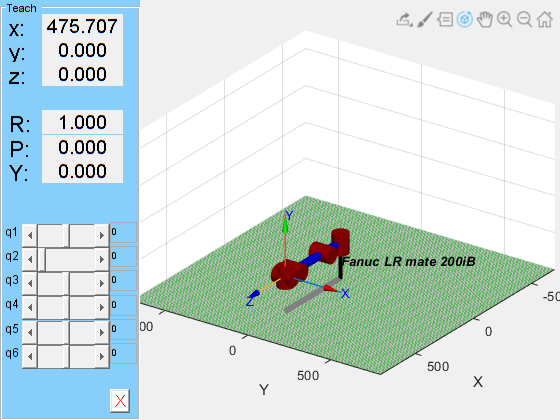

trplot(TCP,'length',2 )

tr2rpy(TCP,'zyx','deg')

ans =    90.0000    0.0000   90.0000



%% para las trayectorias se emplea:
T0=transl(0.4,0.2,0) * trotx(pi);
T1=transl(-0.4,-0.2,0.3) * troty(pi/2);
T = ctraj(T0, T1, 50);
T(:,:,1) %primera pose
T(:,:,10) %decima pose
clf; tranimate(T)

### Robotics Systems Toolbox (RST) de MATLAB®

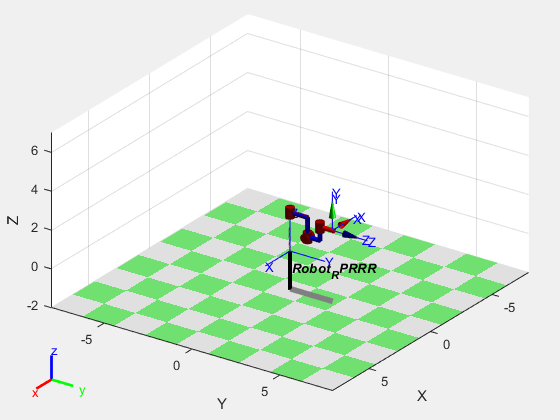

Robot_Fanuc = loadrobot("kinovaGen3",'DataFormat','row','Gravity',[0 0 -9.81]); %importacion del robot
ActualRobotJConfig = homeConfiguration(Robot_Fanuc); %definicion del Home segun el RObot Importado
numJoints = numel(ActualRobotJConfig); %numero de Juntas
endEffector = "EndEffector_Link";      %
show(Robot_Fanuc);

timeStep = 0.1;                        % tiempo de desplazamiento en segundos
toolSpeed = 0.1;                       % Velocidad de la herramienta en m/s 
jointInit = ActualRobotJConfig;        %configuracion inicial del efector final
taskInit = getTransform(Robot_Fanuc,jointInit,endEffector); %inicio de la tarea de movimiento

taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]); %coordenadas finales de la tarea




robot = loadrobot('fanucLRMate200ib');

Error using loadrobot (line 46)
Expected robotName to match one of these values:

'abbIrb120', 'abbIrb120T', 'kinovaGen3', 'kinovaJacoJ2N6S200', 'kinovaJacoJ2N6S300', 'kinovaJacoJ2N7S300', 'kinovaJacoJ2S6S300', 'kinovaJacoJ2S7S300', 'kinovaJacoTwoArmExample', 'kinovaMicoM1N4S200', 'kinovaMicoM1N6S200', 'kinovaMicoM1N6S300', 'rethinkBaxter', 'willowgaragePR2'

The input, 'fanucLRMate200ib', did not match any of the valid values.



show(robot);

PARTE 3

JACOBIANO